# Backtest Performance Measures Test File  

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 14/09/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path to **backtest** function folder

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path to **benchmark** function folder *(Later the benchmark class can become a deriviative class to the backtest class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));

Set path to **HRP** function folder *(Later the benchmark class can become a deriviative class to the benchmark class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/'));
% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
% Backtest images
imageExportpath_bt = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Backtesting/',exportName);
% Structural test images
imageExportpath_st = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Structural_Testing/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

fileName = 'DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)
fileName = 'DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat';
load(fileName)

% Find the minimum value and its index in the JIBA3M column
[minValue, minIndex] = min(M_Ret_TT.Cash);

% Get the date corresponding to the minimum value
minDate = M_Ret_TT.Time(minIndex);

2.1 Create ASSETCL plot names (excludes the underscore)

% rename the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(M_Ret_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(BALFUN_PlotNames, 'TR', '');

plot(M_Ret_TT.ALB_Index)

## 3. Backtest Model Variations 

% Options: and required parameters

%            - none (default) 

%            - rolling_w    (window)

%            - exp_decay    (tau)

%            - crisp        (alpha, z_target)

%            - kernel       (h, gamma, z_target)

%            - e_pooling    (alpha, tau_prior, z_target)

%            - ew_ensemble  (alpha, tau_prior, z_target)

%            - cb_ensemble  (alpha, tau_prior, z_target,ensemble_wt_method)

Window_len = 12;
tau = 12;
alpha = 0.3;
z_target = 'mean';
h = 0.5;
gamma = 2;
tau_prior = 1*12; % Ann did 5 yrs
ensemble_wt_method = 'log-linear';

% this currently set up to test cb_ensemble for backtest_moments.m function
hsfp_parameters = struct('window',[],'tau',[],'alpha',[],'z_target',[], ...
    'gamma',[],'h',[], 'tau_prior',[],'ensemble_wt_method',[]);

hsfp_parameters.window = Window_len;
hsfp_parameters.tau = tau;
hsfp_parameters.alpha = alpha;
hsfp_parameters.z_target = z_target;
hsfp_parameters.h = h;
hsfp_parameters.gamma = gamma;
hsfp_parameters.tau_prior = tau_prior;
hsfp_parameters.ensemble_wt_method = ensemble_wt_method;

backtest_object = struct('returns',[],'Wts_lb',[],'Wts_ub',[],'signals',[],'method',[], 'parameters',[]);
% Returns Timetable
backtest_object.returns = M_Ret_TT;
% CONTROL BOUNDS: lower and upper bounds for asset weights 
backtest_object.Wts_lb = [ 0 0 0 0 0 ]; 
backtest_object.Wts_ub = [ 1 1 1 1 0.05];
% Ensemble needs more than 1 signal series
backtest_object.signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_SAMYM3Y_Index...
     , SIG_SMOOTHED_TT.SAVIT40_Index);
backtest_object.method = 'none';
backtest_object.parameters = hsfp_parameters;

% Test backtest moment calculation
% [hsfp_mu, hsfp_cov,p] = backtest_moments(backtest_object);

### 3.1 Call the backtest_function

Window = 36;
    
[Rolling_portfolioSet,Realised_tsPIndx,Realised_tsPRet_TT,Opt_tsWts,cov_con_n] = backtest_analysis(backtest_object, Window);

% geo_SR_excessRet = zeros(1,width(SR_dif_t));
% f = 12;
% for port = 1:width(SR_dif_t)
% 
%     PRet = SR_dif_t(:,port);
%     % Number of periods under analysis
%     n = height(PRet);
%     % Calculate the geometric mean return (in decimals)
%     geo_SR_excessRet(port) = ((prod(1 + PRet))^ (f / n)) - 1;
% end
% 
% SR_dif_sd = std(SR_dif_t,1);
% 
% test_geo_SR = geo_SR_excessRet./SR_dif_sd;


#### 3.1.1 Plot Inital Backtest output

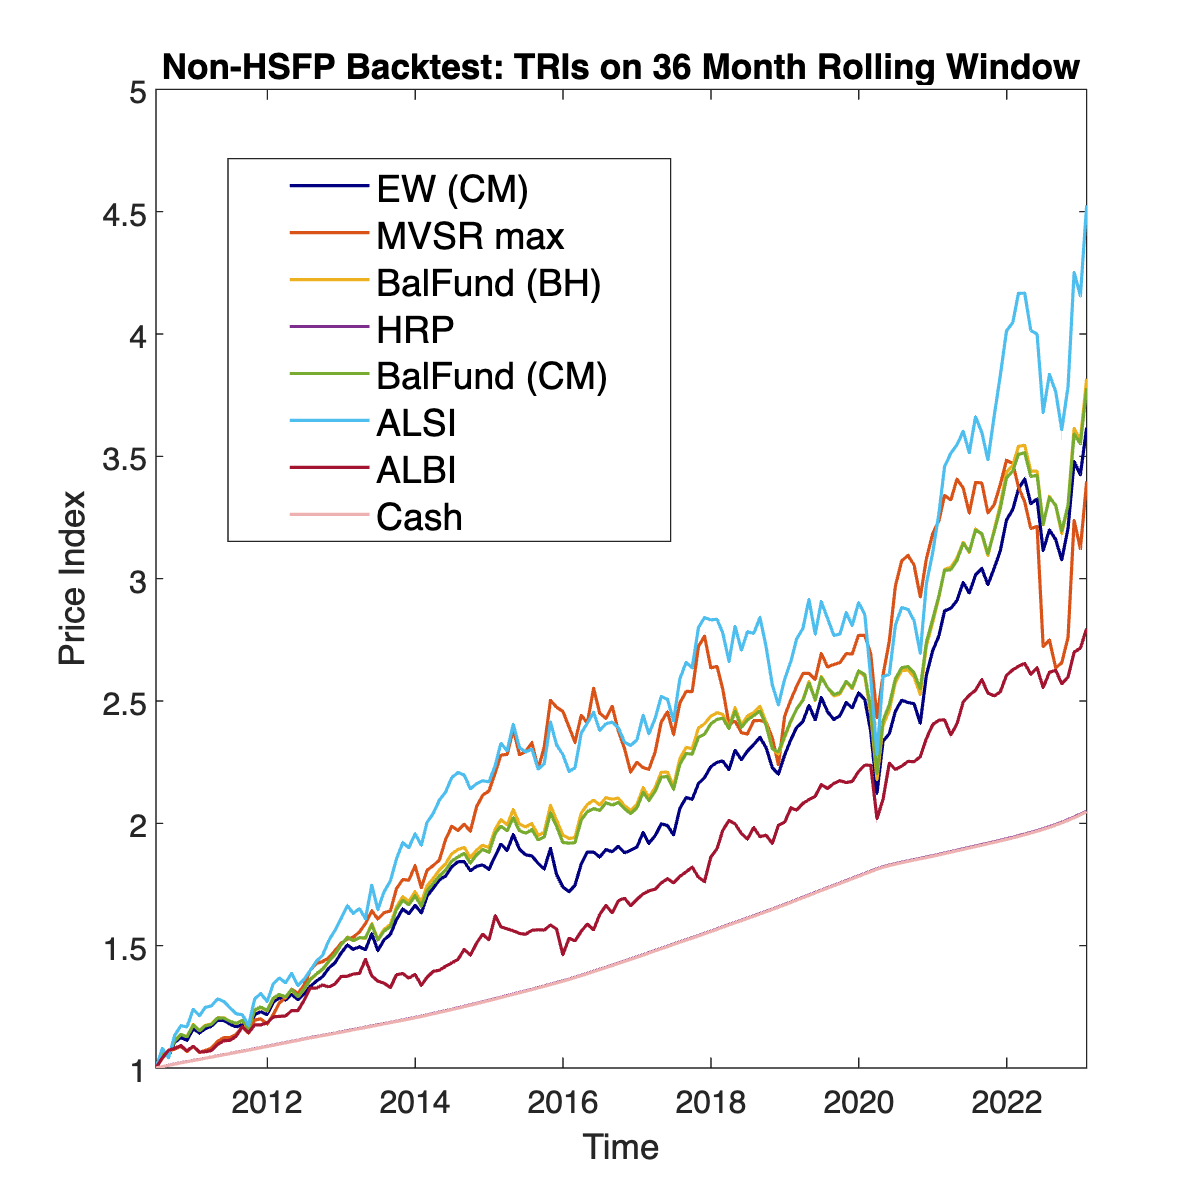

figure('InnerPosition', [100, 100, 600, 600]);

colours = [[0, 0, 0.5];           % blue
    0.8500 0.3250 0.0980;  % orange
    0.9290 0.6940 0.1250;  % yellow,
    0.4940 0.1840 0.5560;  % purple
    0.4660 0.6740 0.1880;  % green
    0.3010 0.7450 0.9330;  % light blue
    0.6350 0.0780 0.1840;  % red
    0.9290 0.6940 0.6940]; % new color (light pink)

numLines = size(Rolling_portfolioSet, 2);
for i = 1:numLines
    lineColor = colours(mod(i-1, size(colours, 1))+1, :);
    plot(Rolling_portfolioSet.Time, Rolling_portfolioSet{:, i}, 'LineWidth', 1.2, 'Color', lineColor);
    hold on;
end

ylabel('Price Index', 'FontSize', 15);
xlabel('Time', 'FontSize', 15);
title(['Non-HSFP Backtest: TRIs on ', num2str(Window), ' Month Rolling Window'], 'FontSize', 16);
legend(Rolling_portfolioSet.Properties.VariableNames, 'Location', 'northwest', 'FontSize', 14);
set(gca, 'FontSize', 12);
UnAdj_36RollW_Output_Plot = gcf;
hold off;

legend("Position", [0.17173,0.5673,0.36486,0.2424])

legend("Position", [0.1896,0.58723,0.36979,0.2424])

## 4. Probabilitic Sharpe Ratio


$$\widehat{P S R}\left(S R^*\right)=Z\left[\frac{\left(\widehat{S R}-S R^*\right) \sqrt{n-1}}{\sqrt{1-\hat{\mu}_3 \widehat{S R}+\frac{\hat{\mu}_4-1}{4} \widehat{S R}^2}}\right]$$


***NOTE: In the backtest set up we calculate an annualised SR.... Are we calculating PSR on an annualised basis as well?***

In the backtest we used cssh as the benchmark ${\textrm{SR}}^*$ here we can first use 0 as the measure of  comparing against no investment skill.


$$\widehat{P S R}\left(S R^*\right)= Pr[S R \leq \widehat{S R}]=\int_{-\infty}^{\widehat{S R}} Z\left(S R \mid S R^*, \hat{\sigma}_{\widehat{S R}}\right) \cdot d S R$$


format longG

#### Remove '0' in realised returns

% Remove the first row from the timetable
Realised_tsPRet_TT(1, :) = [];

### 4.1 Test components: Estimate Sharpe Ratio (geo_sr.m) CONFIRMED using EW port

Rolling_portfolioSet.Properties.VariableNames
% TEST GEOMETRIC AVERAGE - set f = 1 so it is just geometric mean and not annualised using f = 12
test_geo_ave = geo_ave(Realised_tsPRet_TT.("EW (CM)"),1)
test_std = std(Realised_tsPRet_TT.("EW (CM)"),1) %% NB: need to decide about /(N-1) or /N

ans = 1×8 cell array
    {'EW (CM)'}    {'MVSR max'}    {'BalFund (BH)'}    {'HRP'}    {'BalFund (CM)'}    {'ALSI'}    {'ALBI'}    {'Cash'}


test_sr =test_geo_ave/test_std
% set f = 1 so it is just geometric mean and not annualised using f = 12

test_geo_ave =        0.00855102673907471


[geo_SR,geo_ExcessRet_ave,ExcessRet_sd] = geo_sr(Realised_tsPRet_TT.("EW (CM)"))

test_std =         0.0279209677230577


### 4.2 Test components: sr_std.m Standard deviation of SR: CONFIRMED

NOTE: sr_std only does 1 asset at a time, not full tables.

% Standard Normal dist needs skewness (mu3) = 0 & kurtosis (mu4) = 3 

test_sr =          0.306258250927782


[ srStd, skew, kurt,T] = sr_std(Realised_tsPRet_TT.("EW (CM)"), 151,0,3)

### 4.2 Test components: PSR

NOTE: psr only does 1 asset at a time, not full tables.

mv_sr = geo_sr(Realised_tsPRet_TT.("EW (CM)"),1)

geo_SR =          0.306258250927782


geo_ExcessRet_ave =        0.00855102673907471


ExcessRet_sd =         0.0279209677230577


mv_sr_Std = sr_std(Realised_tsPRet_TT.("EW (CM)"))
eval_sr = normcdf((mv_sr - 0) / mv_sr_Std)

### 4.3 Call PSR: 

test_psr = psr(Realised_tsPRet_TT.Cash, 0)

srStd =         0.0835422870220294


skew =      0


kurt =      3


T =    151


format shortG

mv_sr =          0.306258250927782


## 5.1 Export Strategy-wise PSRs:

For each strategy create a cross tab of the strategy sr and alternative benchmark strategy:

J = size(Rolling_portfolioSet,2);

mv_sr_Std =         0.0876347569057823


port_psr = zeros(J,J);

eval_sr =          0.999762713372724


% 
% for bench_port = 1:J
%   for strategy = 1: J

test_psr =      1


%     port_psr(bench_port, strategy) = psr(Realised_tsPRet_TT{2,strategy},Realised_tsPRet_TT{2,bench_port});
%   end
% end

for strategy = 1:J
    for bench_port = 1:J
        port_psr(bench_port, strategy) = psr(Realised_tsPRet_TT{:, strategy}, Realised_tsPRet_TT{:, bench_port});
    end
end

## 5. 2 Export NO investment skill PSRs:

For each strategy create a cross tab of the strategy sr and alternative benchmark strategy:

J = size(Rolling_portfolioSet,2);
base_psr = zeros(J,J);
for strategy = 1:J
    for bench_port = 1:J
        base_psr(bench_port, strategy) = psr(Realised_tsPRet_TT{:, strategy}, 0);
    end
end

### 5.2.1 Export latex table

sympref('FloatingPointOutput',1);
latex_table = latex(sym(round(port_psr,4 )));
